syms theta Dtheta DDtheta mp g l
mp=2;g=9.81;l=2

l = 2

Ip=mp*l*l;
tau=0

tau = 0

k=0.1;
eq=-tau+mp*g*sin(theta)*l -k*Dtheta==Ip*DDtheta

$$eq = 39.2400\,\sin\left(\theta \right)-0.1000\,\mathrm{Dtheta}=8\,\mathrm{DDtheta}$$


sol=solve(eq,DDtheta)

$$sol = 4.9050\,\sin\left(\theta \right)-0.0125\,\mathrm{Dtheta}$$

DDtheta(Dtheta,theta)=sol

$$DDtheta(Dtheta, theta) = 4.9050\,\sin\left(\theta \right)-0.0125\,\mathrm{Dtheta}$$

Now Integrate

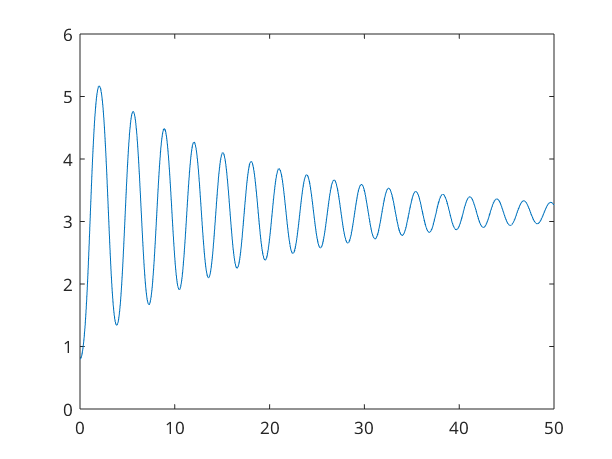

Dtheta_0=0;
theta_0=0.8;
y0=[theta_0,Dtheta_0].';
tspan=0:0.01:50;
options = odeset('RelTol',1e-20,'AbsTol',1e-20);
[t,y]=ode45(@pend,tspan,y0);
figure(1)
plot(t,y(:,1))

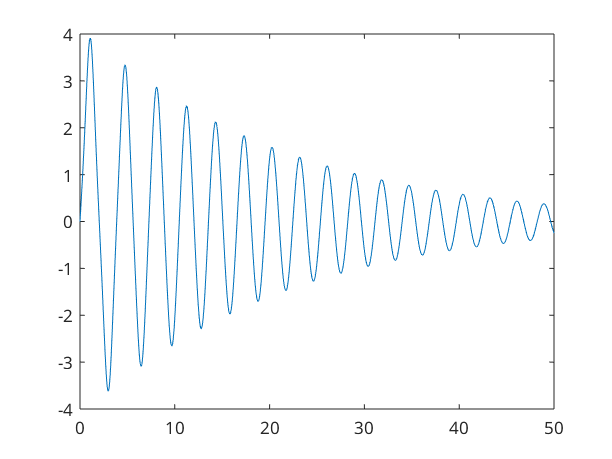

figure(2)
plot(t,y(:,2))

try

syms a b c
x=[a b c]' %is a 3*1 vector, and its 3*3 skew symmetric matrix is 

$$x = \left(\begin{array}{c} \bar{a}\\ \bar{b}\\ \bar{c} \end{array}\right)$$

X=[0   -c   b ;
 c    0  -a ;
-b    a   0  ];
A(a,b,c)=X*eye(3)*x

$$A(a, b, c) = \left(\begin{array}{c} b\,\bar{c}-c\,\bar{b}\\ c\,\bar{a}-a\,\bar{c}\\ a\,\bar{b}-b\,\bar{a} \end{array}\right)$$

A(1,0,0)

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$